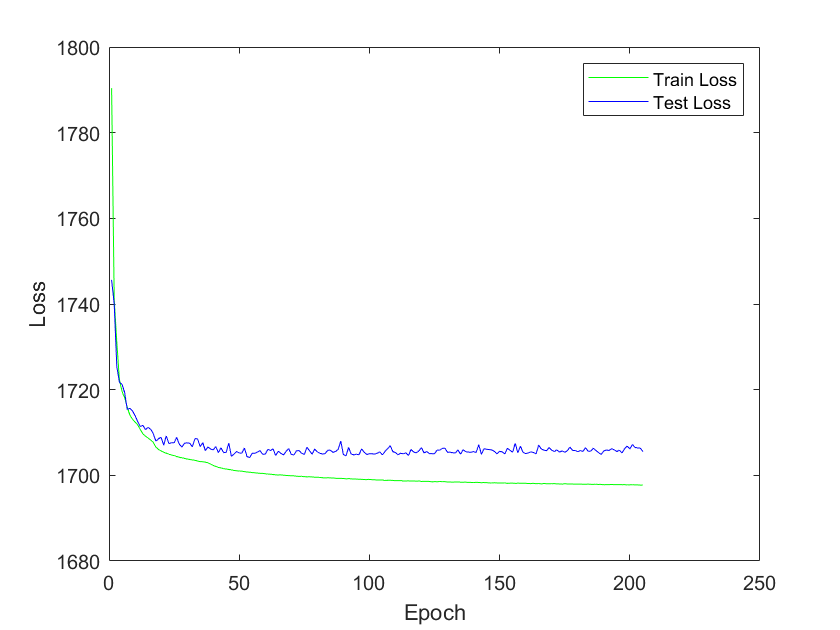

%     Created on Tuesday, Jun 16 2020
% 
%     Author           : Yu Du
%     Email            : yuduseu@gmail.com
%     Last edit date   : Wednesday, Jun 20 2020
% 
% South East University Automation College
% Vision Cognition Laboratory, 211189 Nanjing China

filename = fullfile('../logs/img_align_celeba_log.txt');
fid = fopen(filename);

C = textscan(fid, '%f%f%f','HeaderLines',0);

plot(C{1}, C{2},'g');
hold on;
plot(C{1}, C{3},'b');
hold off;
xlabel('Epoch');
ylabel('Loss');
% ylim([0 0.005]);
legend('Train Loss', 'Test Loss','Location', 'northeast')
savefig('Loss_deep');